# Evaluación 7.1 (Trayectorias en lazo abierto)

Jonathan Josafat Vazquez Suarez - A01734225

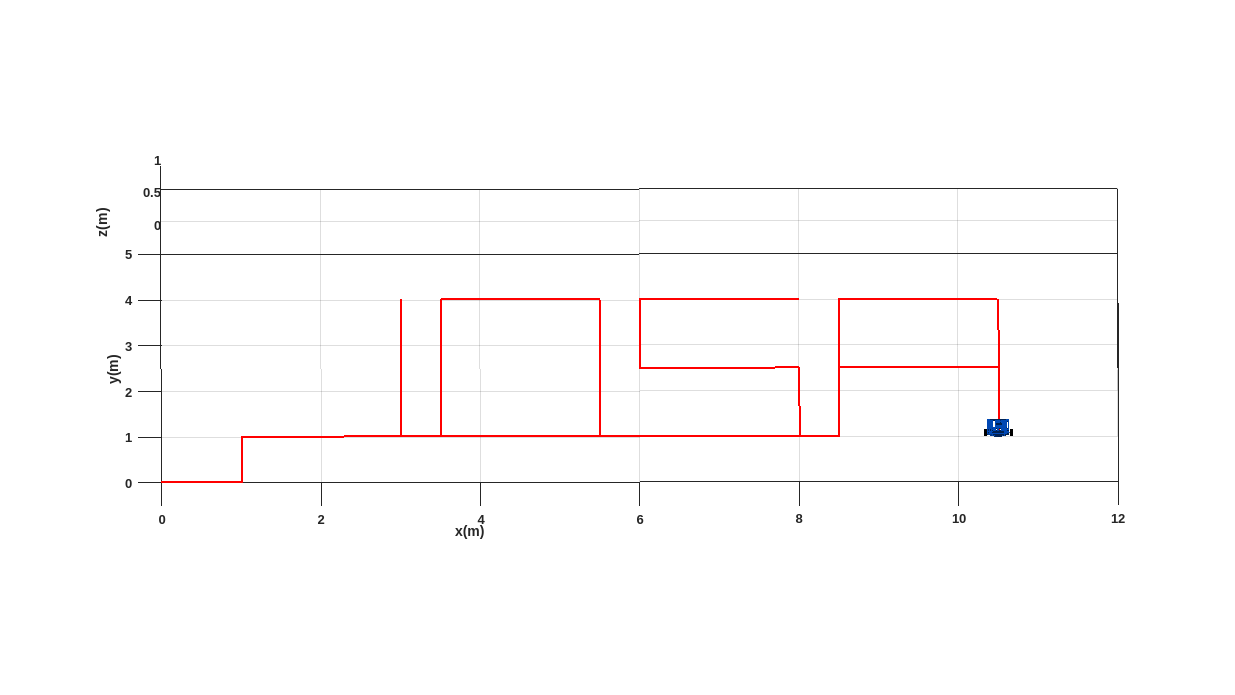

%Calculo de trayectoria a partir de coordenadas, 
% usamos un delta de tiempo de 1 segundo para cada paso en coordenada
coord_1_x = [1, 1, 3, 3, 3, 5.5, 5.5, 3.5, 3.5, 8, 8, 6, 6, 8, 6, 6, 8, 8, 8.5, 8.5, 10.5, 10.5, 8.5, 10.5, 10.5];
coord_1_y = [0, 1, 1, 4, 1, 1, 4, 4, 1, 1, 2.5, 2.5, 4, 4, 4, 2.5, 2.5, 1, 1, 4, 4, 2.5, 2.5, 2.5, 1];

%Funcion adjuntada para el calculo de velocidad lineal y angular en cada
%tramo de la trayectoria
[v, w] = setSteps(coord_1_x, coord_1_y);

%Calculo cinematico del movimiento al robot
[N, x, y, phi, hx, hy] = cinematicMobile(v, w);

% Plotting of the robot's movement using the calculated kinematics and coordinates
plotRobot(N, x, y, phi, hx, hy, 0, 12, 0, 5);

El script es un diseño de trayectorias en lazo abierto, es decir, no obtiene una retroalimentacion de control, el funcionamiento esta basado en el movimiento lineal y angular, durante un lapso de tiempo generamos velocidades que trasladan o rotan al robot, debido a que el mezclar ambos tipos de movimientos genera trayectorias complejas, el resultado es por pasos, es decir, rotacion y luego traslacion, por lo que generamos pares de vectores de tamaño n donde por tramos, la velocidad angular tenga valores y lineas con ceros, tras otro tramo donde velocidad angular sea cero y lineal con valor, para poder definir exactamente la velocidad que tendra en las velocidades para obtener el cambio deseado (rotacion o traslacion), tenemos dos opciones, escalar nuestras velocidades de tal forma que en i pasos complete la trayectoria deseada o definir la velocidad deseada y establecer la cantidad de pasos. Para este caso, el robot funciona creando tramos de vectores de tamaño 10, donde dependiendo de nuestra distancia o rotacion deseada, ajustamos la velocidad para que en un tiempo especifico complete los 10 pasos y con la velocidad obtenida complete el trayecto a los necesitado. Se explcia a detalle el funcionamiento del codigo con las siguientes preguntas. 

**a) **¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?

Explicado el funcionamiento general, podemos referenciar a nuestra funcion  "setSteps", la cual se encarga de recibir las coordenadas deseadas y generar el trayecto esperado en un vector resultando, para calcular distancia es simplemente una resta de distancias y srqt((x2-x1)**2 + (y1-y1)**2), calculamos para un tiempo unitario (un segundo), la velocidad que debe tener para dezplazarse ese tiempo, mientras que nuestra velocidad angular se mantiene en cero, por lo que tendriamos algo como v = [velocidad * ones(1, 10)] && w = [0 * ones(1, 10)]

**c) **¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?

Para la rotacion tenemos el mismo proceso, primero necesitamos saber con exactitud el angulo que debemos rotar, para eso usamos atan2(y, x) y una vez encontrado tenemos el misom proceso pero con velocidad angular v = [0 * ones(1,10)] && w = [velocidad * ones(1,10)]

*Para poder mantener el historico de velocidades y poder mantener el estilo de codificacion por tramos debemos hacer un merge entre el vector y el nuevo calculo, en este caso la sintexis de matlab es la siguiente: vector = [vector, nuevo_vector], esto genera un vector unico que no aumenta sus dimensiones.

**b)** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?

El cambio de preguntas es generado debido a que una trayectoria curva es el conjunto entre un giro y una trayectoria recta, por lo que para tener una trayectoria curva lo unico que debemos es tener velocidades angulares y lineales juntas, si tenemos un mismo vector de tiempo podriamos tener la trayectoria curva deseada. 

**d****)** ¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

El vector de tiempo es calculado dentro de nuestra funcion cinematicMobile este toma en cuenta el tamaño de nuestras velocidades para poder asumir tramos de un segundo por cada 10 posiciones de nuestro vector, esto debido a como esta programada la funcionalidad que deseamos implementar,  por lo que nuestro tiempo es obtenido como t = lenght(v)/10. El valor del tiempo nos ayuda a dezplazarnos correctamente, esto es parte de lo aclarado sobre el como vamos a dezplazarnos, ya que nuestras velocidades estan calculados a un tiempo de un segundo, aumentarlo o reducirlo haria que nuestro robot gire mas o menos o en su defecto se desplace una mayor o menos distancia. 

**e****)** ¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

Para obtener las dimensiones deseadas solo era necesario ajustar nuestras velocidades, cuando se quiere dezplazarse y cuanto se quiere rotar, para obtener una distancia de 3 metros nuestro robot mantiene una velocidad de 3 metros por segundo, para girar nuestro robot tiene una velocidad angular de atan2((y2-y1), (x2-x1)) - angulo_actual.